% clear
% clc
% close all;

N = 10^6;
PSK = 2; 
SNR = 0:20;
Nt = 2;
Nr = 2;              % No of antennas at Rx and Tx

data = randi([0 PSK-1], Nt, N);

s_bpsk = pskmod(data, PSK, 0, 'Gray');
s_qam = qammod(data,16,'gray');

% MIMO channel

H = ( randn(Nr, Nt) + 1i*randn(Nr, Nt) ) / sqrt(2);
w = (H'*H)\(H');

bit_errors_bpsk = zeros(size(SNR));
bit_errors_qam = zeros(size(SNR));

% Addition of Noise
for p=1:length(SNR)
    received_s_bpsk = awgn(H*s_bpsk, SNR(p));
    received_s_qam = awgn(H*s_qam, SNR(p));

    % Zero Forcing (ZF) technique
    estimated_s_bpsk = w*received_s_bpsk;
    estimated_s_qam = w*received_s_qam;
    estimated_data_bpsk = pskdemod(estimated_s_bpsk, PSK, 0, 'Gray');
    estimated_data_qam = qamdemod(estimated_s_qam,16,'gray');
    bit_errors_bpsk(p) = biterr(data, estimated_data_bpsk);
    bit_errors_qam(p) = biterr(data, estimated_data_qam);
end

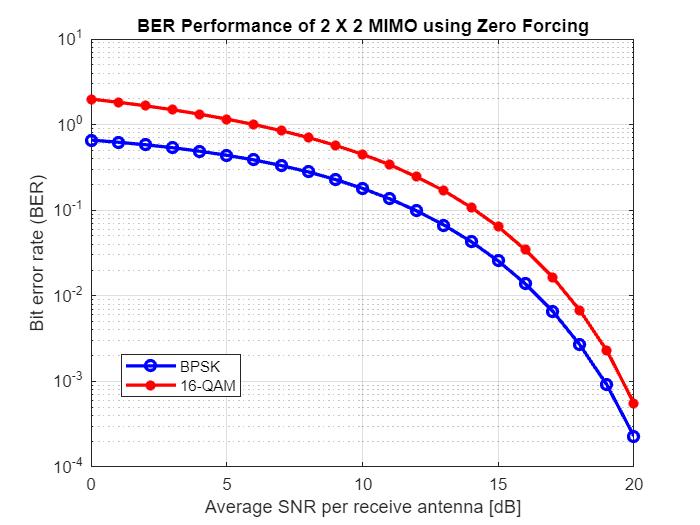

BER_bpsk_zf = bit_errors_bpsk/N;
BER_qam_zf = bit_errors_qam/N;
semilogy(SNR,BER_bpsk_zf,'bo-','LineWidth',2);
grid on;
hold on;
semilogy(SNR,BER_qam_zf,'r*-','LineWidth',2);
title('BER Performance of 2 X 2 MIMO using Zero Forcing');
xlabel('Average SNR per receive antenna [dB]');
ylabel('Bit error rate (BER)');
legend('BPSK', '16-QAM','Location',"best");